# GC-FID Data Analysis in MATLAB

This script processes Gas Chromatography-Flame Ionization Detector (GC-FID) data obtained from Agilent instruments. 

## Overview of the Script

The script performs several key tasks:

1. ***Extract Solvent Chromatograms***: The script reads and stores solvent chromatograms from GC-FID data files. 2. ***Extract Measurement Chromatograms***: The script reads and stores measurement chromatograms from GC-FID data files. 3. ***Interpolation of Chromatograms***: All chromatograms are interpolated to have the same time points. 4. ***Solvent Subtraction***: The average solvent signal is subtracted from the measurement signals. 5. ***Baseline Correction***: Baseline correction is applied to the measurement signals. 6. ***Noise Filtering***: The script allows the user to manually filter out noise in the chromatograms. 7. ***Peak Detection***: Peaks in the chromatograms are detected using MATLAB’s built-in `findpeaks` function. 8. ***Peak Matching***: The script matches peaks across the three chromatograms using dynamic ellipse-based error bounds. 9. ***Peak Fitting***: Detected peaks are fitted to model the chromatograms, and integration is performed to quantify the peaks.

## Adjustable Parameters

The script allows users to adjust several key parameters:

- ***File Paths***: Modify the paths for solvent and measurement chromatograms.

- ***Interpolation Method***: Choose the interpolation method for aligning chromatograms.

- ***Peak Detection Parameters***: Adjust thresholds for peak height, prominence, width, and distance.

- ***Baseline Correction Settings***: Customize the window size, step size, and smoothing method for baseline correction.

- ***Ellipse Error Bounds***: Change the error bounds used for matching peaks across chromatograms.

## **!! Before Running Code, clear all Outputs !!**

## 1. Extract Solvent Chromatograms

The script begins by extracting chromatograms from the solvent data files. The data is read using a custom MATLAB function `ImportAgilentMod`, which parses Agilent data files.

clear all; clc; clf('reset'); 
folders = ["FitFunctions", "Functions", "Raw Data", "Calibration files", "Pictures"];
for folder = folders
    addpath(genpath(folder));
end
clear folders folder
%S = dir('.\solvent_5\*.D');  % Directory containing solvent chromatograms
Sbase = "C:\Users\Gabriel P15G2\Desktop\ChromatographyAnalyzerLocal\Raw Data\solvent_1";
S = dir(Sbase+'\*.D');
% Initialize cell arrays for storing time and signal data
%ts = cell(1,3); 
%ss = cell(1,3); 
loopNumberSolv = length(S);
% Loop over the first 3 solvent files and extract data
for i = 1:loopNumberSolv                                                                 
    fld = [S(i).folder, '\', S(i).name];   % Construct the full file path
    data = ImportAgilentMod(fld);          % Import data using a custom function
    ts{i} = data.time;                     % Store time data in a cell array
    ss{i} = data.tic;                      % Store signal data in a cell array
end

% Each solvent chromatogram may have a different number of data points, so they are stored in cell arrays.
% These chromatograms will later be interpolated to align them temporally.

## 2. Extract Measurement Chromatograms

Similar to the solvent chromatograms, the measurement chromatograms are extracted and stored in cell arrays.

%M = dir('.\measurement_5\*.D');  % Directory containing measurement chromatograms
Mbase = "C:\Users\Gabriel P15G2\Desktop\ChromatographyAnalyzerLocal\Raw Data\measurement_1";
 
M = dir(Mbase+'\*.D');
% Initialize cell arrays for storing time and signal data
%tm = cell(1,3); 
%sm = cell(1,3);
loopNumberMeas = length(M);
% Loop over the first 3 measurement files and extract data
for i = 1:loopNumberMeas
    fld = [M(i).folder, '\', M(i).name];   % Construct the full file path
    data = ImportAgilentMod(fld);          % Import data using a custom function
    tm{i} = data.time;                     % Store time data in a cell array
    sm{i} = data.tic;                      % Store signal data in a cell array
end
clear data Mbase M S fld Sbase loopNumberMeas loopNumberSolv;

## 3. Baseline Correction

Baseline correction is applied to each measurement chromatogram using the `msbackadj` function. 

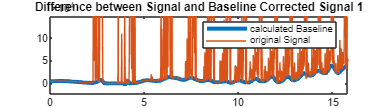

% Determine the common time range by finding the intersection of time ranges across all chromatograms
t_min = max(cellfun(@min, [ts tm]));  % Largest initial time
t_max = min(cellfun(@max, [ts tm]));  % Smallest final time

% Define a new time array with increased point density
time = linspace(t_min, t_max, 4*max(cellfun(@length, [ts tm])));

% Initialize matrices for storing interpolated signals
s_solv = zeros(length(time), 3);  
s_meas = zeros(length(time), 3);

% Interpolate each chromatogram using spline interpolation
for i = 1:3
    s_solv(:, i) = interp1(ts{i}, ss{i}, time, "spline");  % Interpolate solvent signals
    s_meas(:, i) = interp1(tm{i}, sm{i}, time, "spline");  % Interpolate measurement signals
end

% This interpolation is crucial to ensure that all chromatograms are temporally aligned, 
% allowing for accurate subtraction and comparison of signals.
% Compute the average solvent signal
s_solv_avg = mean(s_solv, 2);

% Subtract the solvent signal from each measurement signal, avoiding negative values
s_meas_ns = s_meas - min(s_meas, s_solv_avg);

% This step helps in eliminating the background signal contributed by the solvent, 
% making it easier to analyze the peaks of interest.
window_size = 900;
step_size = 900;
regression_method = "pchip";
estimation_method = "quantile";
smooth_method = "rloess";
quantile_value = 0.08;
preserve_heights = false;
 

% Initialize matrix for storing baseline-corrected signals
s_meas_ns_bc = zeros(size(s_meas_ns)); 

% Apply baseline correction to each chromatogram
for i = 1:3
    s_meas_ns_bc(:, i) = msbackadj((1:size(s_meas_ns, 1))', s_meas_ns(:, i), ...
        "WindowSize", window_size, ...
        "StepSize", step_size, ...
        "RegressionMethod", regression_method, ...
        "EstimationMethod", estimation_method, ...
        "SmoothMethod", smooth_method, ...
        "QuantileValue", quantile_value, ...
        "PreserveHeights", preserve_heights);
end
whatSig = 1;
set(gcf, 'Units', 'normalized', 'Position', [0 0 1 0.5]);
cla; clf('reset');
diff_bc = s_meas_ns-s_meas_ns_bc;
plot(time,diff_bc(:,whatSig),"LineWidth",3);
hold on;
plot(time,s_meas_ns(:,whatSig));
ylim([min(diff_bc,[],"all")*0.97,max(diff_bc,[],"all")*1.1]);
title(['Difference between Signal and Baseline Corrected Signal ',num2str(whatSig)]);
legend("calculated Baseline","original Signal");
hold off;

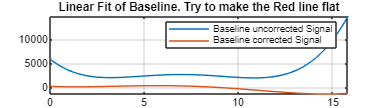

Degree = 4;
[ycon,xcon]=findpeaks(-s_meas_ns(:,1),time,"MinPeakHeight",-5000);
[ycon_bc,xcon_bc]=findpeaks(-s_meas_ns_bc(:,1),time,'MinPeakHeight',-5000);
%f = fit(xcon',-ycon,'smoothingspline','SmoothingParam',1);
%f_bc = fit(xcon_bc',-ycon_bc,'smoothingspline','SmoothingParam',1);
%f = interp1(xcon,ycon,time,'pchip');
%f_bc = interp1(xcon_bc,ycon_bc,0:1:max(time),'makima');
coeff_bc = polyfit(xcon_bc,-ycon_bc,Degree);
yline_bc = polyval(coeff_bc,time);
coeff = polyfit(xcon,-ycon,Degree);
yline = polyval(coeff,time);

plot(time,yline,'DisplayName','Baseline uncorrected Signal');
hold on;
plot(time,yline_bc,'DisplayName','Baseline corrected Signal');
%fplot=plot(f,'m');
%fplot.DisplayName='Fit for Uncorrected Signal';
%f_bcplot=plot(f_bc,'r');
%f_bcplot.DisplayName='Fit for Baseline Corrected Signal';
%plot(time,f);
%plot(0:1:max(time),f_bc);
legend('show');
title('Linear Fit of Baseline. Try to make the Red line flat');
grid on;
hold off;

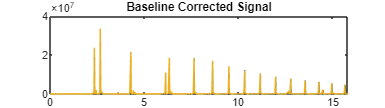


for i = 1:3
    plot(time, s_meas_ns_bc(:,i));
    hold on;
end
title('Baseline Corrected Signal');
hold off;

% Baseline correction is essential for accurate peak detection, as it removes low-frequency noise from the signal.

## 4. Removing Negative Values

Remove negative Values produced by the Baseline correction. This is not Necessary but improves general Results

clear s_meas_ns yline yline_bc coeff Degree coeff_bc ycon xcon ycon_bc xcon_bc whatSig diff_bc sm tm ...
    s_solv_avg sm s_meas s_solv t_min t_max ts ss regression_method smooth_method step_size window_size quantile_value ...
    preserve_heights estimation_method
s_meas_ns_bc(s_meas_ns_bc < 0) = 0;
 

## 5. Noise Filtering (User Interaction)

If the Data contains added Noise produced by the Baseline correction and this noise cannot be negated by careful Baseline Correction parameter selection, it must be manually removed.

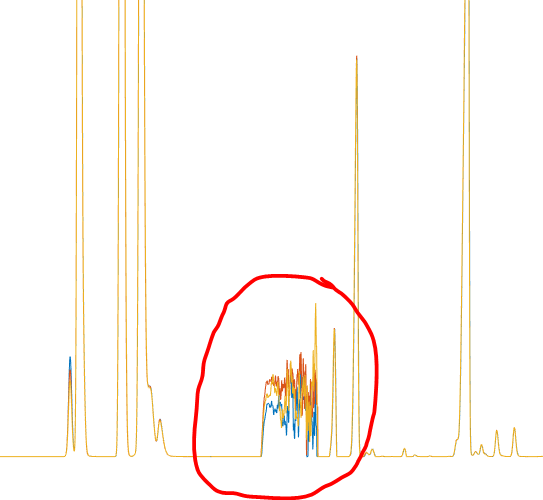 

This Noise will look like above and you can remove it by pressing the Button "Manual Correction", which will open an extra window.

QmanualCorr = true;
 
% exported as a seperate function in order to work with live script
if QmanualCorr
    s_meas_ns_bc = NoiseFilter(time, s_meas_ns_bc);
end

## 6. Peak Detection

Detect peaks in each of the baseline-corrected measurement signals.

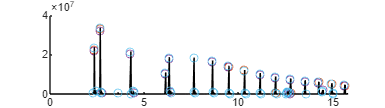

% Initialize cell arrays for storing peak information
%pks = cell(1, 3);  % Peak values
%locs = cell(1, 3);  % Peak locations (time)
%w = cell(1, 3);  % Peak widths

% Parameters for peak detection
min_peak_height = 220000;  % Minimum height of detected peaks
min_peak_prominence = 100;  % Minimum prominence of detected peaks
min_peak_distance = 0.01;  % Minimum distance between peaks (in time)
min_peak_width = 0.001;  % Minimum width of detected peaks
max_peak_width = 16;  % Maximum width of detected peaks
threshold = 0;  % Threshold for peak detection
width_reference = 'halfheight';  % Reference for peak width calculation
 
% Loop over each chromatogram to detect peaks
for i = 1:3
    [pks{i}, locs{i}] = findpeaks(s_meas_ns_bc(:, i), time, ...
        "MinPeakHeight", min_peak_height, ...
        "MinPeakProminence", min_peak_prominence, ...
        "MinPeakDistance", min_peak_distance, ...
        "MinPeakWidth", min_peak_width, ...
        "MaxPeakWidth", max_peak_width, ...
        "Threshold", threshold, ...
        "WidthReference", width_reference);
end
locs = cellfun(@(x) x',locs,'UniformOutput',false);
cla; clf('reset');
hold on;
for i=1:3
    plot(time,s_meas_ns_bc(:,i),'k');
    scatter(locs{i},pks{i});
end

clear max_peak_width min_peak_width min_peak_distance min_peak_prominence min_peak_height threshold ...
    width_reference
% This section detects peaks based on various customizable parameters such as height, width, and distance.

## 7. Finding Common Peaks Across Chromatograms

Identify common peaks across the three chromatograms using an elliptical error tolerance method.

Mostly leave the Intial Values intact and play around with the Percentages

% Define error bounds
errorBoundX = 0.02; % Example error bound for x direction (semi-major axis)
errorBoundY = 300000; % CHANGE THE SCALING TO EASIER VALUES HERE
errorBoundXPercentage = 20;
errorBoundYPercentage = 40; % Example error bound percentage for y direction (semi-minor axis)
 
cla; clf('reset');
% Find common peaks and plot ellipses
[commonPeaks,~] = findCommonPeaksWithEllipsesV18orig(errorBoundX,errorBoundY, errorBoundYPercentage, errorBoundXPercentage,locs,pks);
for i=1:2:5
    if (numel(unique(commonPeaks(:,i))) < numel(commonPeaks(:,i)))
        disp(['there are doubles in list:', num2str(i)]);
        disp('!!please make the ellipse smaller in the horizontal direction or cut noise!!')
    end
end
if (numel(unique(commonPeaks(:,1:2:5))) < numel(commonPeaks(:,1:2:5)))
    disp("there are doubles");
end

there are doubles


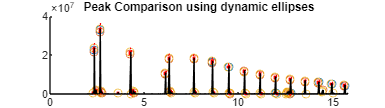

hold on;
for i=1:3
    plot(time,s_meas_ns_bc(:,i),'k');
end
hold off;

## Manual Removal of Irrelevant Peaks or Addition of Interesting Peaks

removePeaks = false;
 
if removePeaks
    updatedCommonPeaks = deselectPeak(time, s_meas_ns_bc, commonPeaks);
    updatedCommonPeaks = updateCommonPeaks(updatedCommonPeaks);
end

addPeaks = false;
 
if addPeaks
    updatedCommonPeaks = SelectPeak(time, s_meas_ns_bc, updatedCommonPeaks);
    updatedCommonPeaks = updateCommonPeaks(updatedCommonPeaks);
end

## 8. Minima proofing

In order to properly fit functions and calculate areas the Signal has to be seperated into bits, for this purpose we invert the signal and find its maximas. Tune the Height Threshold parameter so the peaks are clearly separated.

They should be clearly separated like so: 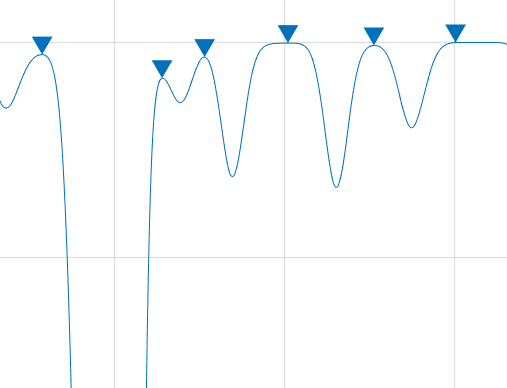

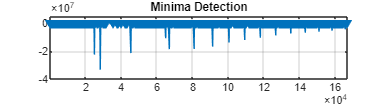

 
height_Threshold_forFitting = 5000;
NegativePeakProminence = 100;
cla; clf('reset');
findpeaks(-s_meas_ns_bc(:, 1), 'MinPeakProminence', NegativePeakProminence);
title('Minima Detection');

## 9. Peak Fitting

Detected peaks are fitted to model the chromatograms using a skewed Normal distribution Model. If this Checkbox is not marked, the Chroamtogram peaks are cut and integrated in the usual fashion as is done by Agilent.

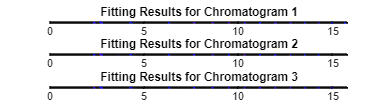

QFunctionFit = true;
warning('off','all');
betaTable = {};
%betaChunkTable = {};
%checkNumberFitsTable ={};
total_x_chunks = {};
total_y_chunks = {};
whattoIntegrate = false(length(commonPeaks(:,1))-1,3);
inwhatChunktoIntegrate = zeros(length(commonPeaks(:,1))-1,3);
figure;
for k = 1:3
    %first_nonzero_idx = find(s_meas_ns_bc(:, k) ~= 0, 1);
    other_zeros = find(s_meas_ns_bc(:,k)' < 100);                           % finds the indices of all entries in s_meas_ns_bc that have a value below 100
    differences = diff(other_zeros);                                        % calculates the difference between each indice, if the indice is other than one, it means the indices are not consecutive and we know this is a parcel of seperated data
    start_of_sequence = [true, differences ~= 1];                           % 
    end_of_sequence = [differences ~= 1, true];
    retain_mask = start_of_sequence | end_of_sequence;
    filtered_array = other_zeros(retain_mask);
    % only keep indexes that are not consecutive
    % add other zeros to minima_locs and then sort them, this way it should
    % be proper
    [~, minima_locs] = findpeaks(-s_meas_ns_bc(:, k), 'MinPeakProminence', NegativePeakProminence); % Find minima locations
    minima_locs_orig = minima_locs;
    if length(other_zeros) > 1 %first_nonzero_idx > 1
        minima_locs = [filtered_array'; minima_locs];
    end    
    minima_locs_sort = sort(minima_locs);
    minima_locs = unique(minima_locs_sort);
    x_chunks = cell(length(minima_locs) + 1, 1);
    y_chunks = cell(length(minima_locs) + 1, 1);

    % Define the chunks based on minima locations
    for i = 1:length(minima_locs) + 1
        if i == 1
            % First chunk: from start to first minimum
            x_chunks{i} = time(1:minima_locs(i));
            y_chunks{i} = s_meas_ns_bc(1:minima_locs(i), k)';
        elseif i == length(minima_locs) + 1
            % Last chunk: from last minimum to end
            x_chunks{i} = time(minima_locs(i-1):end); % WHAT IS THE LAST OR FIRST CHUNK HAS A DOUBLE PEAK VALLEY VALUE LIKE ONE OF THE MIDDLE CHUNKS HAD?
            y_chunks{i} = s_meas_ns_bc(minima_locs(i-1):end, k)';
        else
            % Middle chunks: between minima
            x_chunks{i} = time(minima_locs(i-1)+1:minima_locs(i));
            y_chunks{i} = s_meas_ns_bc(minima_locs(i-1)+1:minima_locs(i), k)';
        end
    end
    
    % Initialize variables to store fitted parameters and results
    fittedChunks = cell(length(x_chunks), 1);
    fitResults = cell(length(x_chunks), 1);
    betaChunks = cell(length(x_chunks), 1); % Store beta values for each chunk
    bestChoiceIndex = cell(length(x_chunks), 1);
    checkNumberFits = cell(length(x_chunks),1);

    % Loop over each chunk and perform peak fitting if the chunk contains a common peak
    %FuncDeconvCommonPeakIndex = 2;
    whichRowinCommonPeaks = find(commonPeaks(1,:)==k);
    ctr = 1;
    for i = 1:length(x_chunks)
        % Check if any common peaks fall within the current chunk
        
        commonArray = ismember(commonPeaks(2:end,whichRowinCommonPeaks),x_chunks{i});
        commonPeakInChunk = any(commonArray);
        
        if commonPeakInChunk
            inwhatChunktoIntegrate(ctr,k) = i;
            ctr = ctr + 1;
        end
        [~,ref] = max(y_chunks{i});
        if min(y_chunks{i}(1:ref)) > height_Threshold_forFitting || min(y_chunks{i}(ref:end)) > height_Threshold_forFitting % change this to a settable value by the customer
            analyse = true;
        else
            analyse = false;
        end
        if commonPeakInChunk && length(x_chunks{i}) > 3 && analyse
            % Perform individual peak fitting for the chunk
            %disp(FuncDeconvCommonPeakIndex);
            momPk = commonPeaks([false;commonArray],whichRowinCommonPeaks+1);
            momMean_val = commonPeaks([false;commonArray],whichRowinCommonPeaks);
            %betaTable(FuncDeconvCommonPeakIndex,k) = momMean_val;
            %FuncDeconvCommonPeakIndex = FuncDeconvCommonPeakIndex +1;  
            %checkNumberFits{i} = momMean_val;
            whattoIntegrate(commonArray,k) = true;
            if QFunctionFit
                [yFit, beta, ~, bestChoiceIndex{i}] = FuncDeconvoluterNLinFitV03(x_chunks{i}, y_chunks{i}, momPk, momMean_val);
                if ~isempty(yFit) % Check if yFit is not empty
                    fitResults{i} = struct('yFit', yFit, 'beta', beta, 'bestChoiceIndex', bestChoiceIndex{i});
                    fittedChunks{i} = yFit{1, 1}; % Store the fitted curve for this chunk
                    betaChunks{i} = beta; % Store the beta values for this chunk
                end
            end
        % else
        %     checkNumberFits{i} = 0;
        end
        
    end
    %disp(FuncDeconvCommonPeakIndex);
    %disp(length(cell2mat(betaChunks')));
    % Combine adjacent chunks if they both have valid fits
    combinedFits = {};
    combinedXs = {};
    %combinedYs = {}; % for debug, REMOVE
    fullBetas = {};
    Rsquare2 = {};
    bestChoiceIndexTot = {};
    i = 1;
    while i <= length(x_chunks)
        if ~isempty(betaChunks{i})
            combinedX = x_chunks{i};
            combinedY = y_chunks{i};
            combinedBeta = betaChunks{i}; % Initialize combined beta with the first chunk's beta
            j = i + 1;
            % Combine adjacent chunks if they have valid fits
            while ~isempty(betaChunks{j}) % && j <= length(x_chunks)
                combinedX = [combinedX, x_chunks{j}];
                combinedY = [combinedY, y_chunks{j}];
                if ~isempty(betaChunks{j,1})
                    combinedBeta = [combinedBeta; betaChunks{j,1}]; % Append beta values from the next chunk
                end
                j = j + 1;
            end
            %
            % Perform combined fitting on the merged chunks using the combined beta values as starting points
            if length(combinedX) > 3 && QFunctionFit
                [yFit, fullBetas{i}, Rsquare2{i},bestChoiceIndexTot{i}] = FuncDeconvoluterNLinFitFullFunction(combinedX, combinedY, combinedBeta);
                if ~isempty(yFit) % Check if yFit is not empty
                    combinedXs{end + 1} = combinedX;
                    %combinedYs{end + 1} = combinedY;
                    clear yFitadd1;
                    yFitadd1 = zeros(length(combinedXs),1); % this is very awkward, has to be fixed
                    for p = 1:length(yFit)
                        yFitadd1 = yFitadd1 + yFit{1,p};
                    end
                    combinedFits{end + 1} = yFitadd1;

                end
            end
            i = j; % Move index to the next unprocessed chunk
        else
            i = i + 1;
        end
    end

    % Plot the original data and the fitted curves
    subplot(3,1,k);
    
    plot(time, s_meas_ns_bc(:, k), 'k'); hold on;
    for i = 1:length(fittedChunks)
        if ~isempty(fittedChunks{i})
            plot(x_chunks{i}, fittedChunks{i}, 'r');
        end
    end
    for i = 1:length(combinedFits)
        plot(combinedXs{i},combinedFits{i}, 'b--');
    end
    hold off;
    title(['Fitting Results for Chromatogram ', num2str(k)]);
    set(gcf, 'Units', 'normalized', 'Position', [0 0 1 0.5]);
    %betaTable(:,k) = cell2mat(betaChunks);
    %betaTable(:,k) = cell2mat(fullBetas');
    betaTable{k} = cell2mat(fullBetas');
    betaChunksTable{k} = cell2mat(betaChunks);
    %checkNumberFitsTable{k} = cell2mat(checkNumberFits);
    total_x_chunks{k} = x_chunks;
    total_y_chunks{k} = y_chunks;


end

warning('on','all');

## 10. Integration

Calculate the area under each fitted peak, which can be used for quantifying the amount of substance corresponding to each peak in the chromatograms.

Set the Threshold for R^2, which is a measure of how good the model functions are fit to the data, if the R^2 Value for a function is below this Threshold, the usual cutting Method is used as in most Chromatography Software.

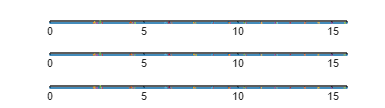

% Initialize table for storing integration results
clear bestChoiceIndexTot bestChoiceIndex tm ts w yFitadd1 yFit x_chunks y_chunks t_min t_max ss s_meas_ns s_solv_avg s_meas s_solv
Areatable = {};
figure;
RThreshold = 0.8;
 
if QFunctionFit
    for p=1:3
        subplot(3,1,p);
        plot(time,s_meas_ns_bc(:,p),'.','MarkerSize',2);
        hold on;
        betas = betaTable{p};
        betas2 = betaChunksTable{p};
        start = 1;
        %SStot = sum((s_meas_ns_bc(:,p)-mean(s_meas_ns_bc(:,p))).^2);
        for i=1:length(whattoIntegrate(:,p))
            if whattoIntegrate(i,p)
                IntVar1 = generateFits(betas(start:start+3),time);
                %IntVar2 = generateFits(betas2(start:start+3),time);
                %IntVar1 = generateFits(betas(start:start+3),total_x_chunks{p}{inwhatChunktoIntegrate(i,p)});
                IntVar2 = generateFits(betas2(start:start+3),total_x_chunks{p}{inwhatChunktoIntegrate(i,p)});
                start = start + 4;
                %R1 = s_meas_ns_bc(:,p)-IntVar1{1}';
                %R2 = s_meas_ns_bc(:,p)-IntVar2{1}';
                %R1 = total_y_chunks{p}{inwhatChunktoIntegrate(i,p)}-IntVar1{1}; % I had done a mistake here where I created a huge matrix by transposing IntVar{1}
                %R2 = total_y_chunks{p}{inwhatChunktoIntegrate(i,p)}-IntVar2{1};
                %SSres1 = sum(R1.^2);
                %SSres2 = sum(R2.^2);
                %Rsq1 = 1-SSres1/SStot;
                %Rsq2 = 1-SSres2/SStot;
                %[MaxRsq,bestFit]=max([Rsq1,Rsq2]);
                bestFit = 0;
                if 1 == 0 %MaxRsq < RThreshold
                    Area = trapz(total_x_chunks{p}{inwhatChunktoIntegrate(i,p)},total_y_chunks{p}{inwhatChunktoIntegrate(i,p)});
                    plot(total_x_chunks{p}{inwhatChunktoIntegrate(i,p)},total_y_chunks{p}{inwhatChunktoIntegrate(i,p)});
                elseif bestFit == 1 %|| abs(Rsq1-Rsq2) > 0.1
                    % Area = trapz(total_x_chunks{p}{inwhatChunktoIntegrate(i,p)},IntVar1{1,1});
                    % plot(total_x_chunks{p}{inwhatChunktoIntegrate(i,p)},IntVar1{1,1});
                    Area = trapz(time,IntVar1{1,1});
                    plot(time,IntVar1{1,1});
                else
                    Area = trapz(total_x_chunks{p}{inwhatChunktoIntegrate(i,p)},IntVar2{1,1});
                    plot(total_x_chunks{p}{inwhatChunktoIntegrate(i,p)},IntVar2{1,1});
                end
                Areatable{p,i}=Area*60;
                %Areatable{p+9,i}=MaxRsq;
            else
                Area = trapz(total_x_chunks{p}{inwhatChunktoIntegrate(i,p)},total_y_chunks{p}{inwhatChunktoIntegrate(i,p)});
                plot(total_x_chunks{p}{inwhatChunktoIntegrate(i,p)},total_y_chunks{p}{inwhatChunktoIntegrate(i,p)});
                Areatable{p,i}=Area*60;
            end
        end  
    end
    set(gcf, 'Units', 'normalized', 'Position', [0 0 1 0.5]);
else
    for p=1:3
        subplot(3,1,p);
        plot(time,s_meas_ns_bc(:,p),'.','MarkerSize',2);
        hold on;
        for i=1:length(whattoIntegrate(:,p))
            Area = trapz(total_x_chunks{p}{inwhatChunktoIntegrate(i,p)},total_y_chunks{p}{inwhatChunktoIntegrate(i,p)});
            plot(total_x_chunks{p}{inwhatChunktoIntegrate(i,p)},total_y_chunks{p}{inwhatChunktoIntegrate(i,p)});
            Areatable{p,i}=Area*60;
        end
    end
    set(gcf, 'Units', 'normalized', 'Position', [0 0 1 0.5]);
end

%%
for i=1:size(Areatable,2)
    Areatable{4,i}=mean([commonPeaks(i+1,1:2:6)]); % mean Peak location
    Areatable{5,i}=mean([Areatable{1:3,i}]); % mean Peak Area
    Areatable{6,i}=std([Areatable{1:3,i}]); % Peak Area Standard Deviation
    Areatable{7,i}=100*Areatable{6,i}/Areatable{5,i}; % Ratio of std to mean
end

## Save and Convert Data

Use Excel Tables with Calibration Data and Compund Identification Data to Convert and Identify Compounds and save them to an Excel you like.

The Values in the Excel files for Calibration and Identification may be changed, but not the layout.

CalibrationTable = "C:\Users\Gabriel P15G2\OneDrive - Montanuniversität Leoben\Montan\Montan\PSI\PSIBeforeLeaving\PSI27092024\mother code\Calibration Files\CalibrationData.xlsx";
IdentificationTable = "C:\Users\Gabriel P15G2\OneDrive - Montanuniversität Leoben\Montan\Montan\PSI\PSIBeforeLeaving\PSI27092024\mother code\Calibration Files\IdentificationData.xlsx";
QSave = false; SaveAs = "try2.xlsx";
 
[AreaData,Result] = CalibratorFunc(Areatable,CalibrationTable,IdentificationTable,QSave,SaveAs);

## Helper Functions

The script also includes several helper functions, such as `findCommonPeaksWithEllipses` for peak matching and `plotEllipse` for visualization of error bounds.

function sortedUpdatedCommonPeaks = updateCommonPeaks(updatedCommonPeaks)
    % Keep the first row unchanged
    firstRow = updatedCommonPeaks(1, :);
    
    % Sort columns 1, 3, and 5, and rearrange columns 2, 4, and 6 accordingly
    [sortedCol1, idx1] = sort(updatedCommonPeaks(2:end, 1));  % Sort column 1 starting from the second row
    sortedCol2 = updatedCommonPeaks(2:end, 2);                  % Column 2 remains the same
    sortedCol2 = sortedCol2(idx1);                              % Rearrange column 2 based on sorted column 1
    
    [sortedCol3, idx3] = sort(updatedCommonPeaks(2:end, 3));  % Sort column 3
    sortedCol4 = updatedCommonPeaks(2:end, 4);                  % Column 4 remains the same
    sortedCol4 = sortedCol4(idx3);                              % Rearrange column 4 based on sorted column 3
    
    [sortedCol5, idx5] = sort(updatedCommonPeaks(2:end, 5));  % Sort column 5
    sortedCol6 = updatedCommonPeaks(2:end, 6);                  % Column 6 remains the same
    sortedCol6 = sortedCol6(idx5);                              % Rearrange column 6 based on sorted column 5
    
    % Combine the first row with the sorted data
    sortedUpdatedCommonPeaks = [firstRow; sortedCol1, sortedCol2, sortedCol3, sortedCol4, sortedCol5, sortedCol6];
    sortedUpdatedCommonPeaks = sortedUpdatedCommonPeaks(any(~isnan(sortedUpdatedCommonPeaks), 2), :);
    %clear sortedCol6 sortedCol5 sortedCol4 sortedCol3 sortedCol2 sortedCol1 idx5 idx3 idx1
end